clc
clear
close all

## Data

g = 9.81;                  %Gravitational Acceleration
M1 = 10;  %Mass Of Ball 1
M2 = 10;  %Mass Of Ball 2
k = 10;    %Spring Constant
L0 = 0.5;                  %Initial Length Of Spring
h = 0.001;                 %Time Interval

## Initial Condition For Frame(X,Y)

For Ball (1): % (X1: Location) , (X1_1=(X1)': Velocity ) , (X1_2=(X1)'': Acceleration ) (Y1: Location) , (Y1_1=(Y1)': Velocity ) , (Y1_2=(Y1)'': Acceleration )

X1 = zeros();   X1(1) = 0.4; % Initial Location For Ball 1
Y1 = zeros();   Y1(1) = 2.1; %
X1_1 = zeros(); X1_1(1) = 5; % Initial Velocity For Ball 1
Y1_1 = zeros(); Y1_1(1) = 1; %



% For Ball (2): % (X2: Location) , (X2_1=(X2)': Velocity ) , (X2_2=(X2)'': Acceleration )
% (Y2: Location) , (Y2_1=(Y2)': Velocity ) , (Y2_2=(Y2)'': Acceleration )

X2 = zeros();   X2(1) = 0.1; % Initial Location For Ball 2
Y2 = zeros();   Y2(1) = 2.5; %
X2_1 = zeros(); X2_1(1) = 1; % Initial Velocity For Ball 2
Y2_1 = zeros(); Y2_1(1) = 5; %



% For Center Of Mass: % (Xc: Location) , (Xc_1=(Xc)': Velocity ) , (Xc_2=(Xc)''= 0: Acceleration )
% (Yc: Location) , (Yc_1=(Yc)': Velocity ) , (Yc_2=(Yc)''=-g: Acceleration )

Xc = zeros(); Xc(1) = (M1*X1(1)+M2*X2(1))/(M1+M2);
Yc = zeros(); Yc(1) = (M1*Y1(1)+M2*Y2(1))/(M1+M2);
Xc0_1 = (M1*X1_1(1)+M2*X2_1(1))/(M1+M2);
Yc0_1 = (M1*Y1_1(1)+M2*Y2_1(1))/(M1+M2);
%Yc_1 = -g*t+ Yc0_1;



% (t: Time Matrix)
t = zeros();   t(1)=0;



X1_2 = @(t,X1,Y1,X2,Y2) k*(((X2-X1)^2+(Y2-Y1)^2).^(1/2)-L0)*(X2-X1)/(M1*((X2-X1)^2+(Y2-Y1)^2).^(1/2));
Y1_2 = @(t,X1,Y1,X2,Y2) -g + k*(((X2-X1)^2+(Y2-Y1)^2).^(1/2)-L0)*(Y2-Y1)/(M1*((X2-X1)^2+(Y2-Y1)^2).^(1/2));

X2_2 = @(t,X1,Y1,X2,Y2) -k*(((X2-X1)^2+(Y2-Y1)^2).^(1/2)-L0)*(X2-X1)/(M2*((X2-X1)^2+(Y2-Y1)^2).^(1/2));
Y2_2 = @(t,X1,Y1,X2,Y2) -g - k*(((X2-X1)^2+(Y2-Y1)^2).^(1/2)-L0)*(Y2-Y1)/(M2*((X2-X1)^2+(Y2-Y1)^2).^(1/2));

Xc_function = @(t) Xc0_1*t + Xc(1);
Yc_function = @(t) -1/2*(g*t.^2) + Yc0_1*t + Yc(1);

## Runge Kutta Algorithm For Moving Frame(X,Y)

A = zeros(1,4);
B = zeros(1,4);
C = zeros(1,4);
D = zeros(1,4);

a = zeros(1,4);
b = zeros(1,4);
c = zeros(1,4);
d = zeros(1,4);

e = [1,2,2,1];

n = 1;
while Yc>0
    
    % FINDIG VELOCITY FROM ACCELERATION
    A(1)=X1_2( t(n) , X1(n) , Y1(n) , X2(n) , Y2(n) );
    B(1)=Y1_2( t(n) , X1(n) , Y1(n) , X2(n) , Y2(n) );
    C(1)=X2_2( t(n) , X1(n) , Y1(n) , X2(n) , Y2(n) );
    D(1)=Y2_2( t(n) , X1(n) , Y1(n) , X2(n) , Y2(n) );
    
    A(2)=X1_2( t(n)+h/2 , X1(n)+h/2*A(1) , Y1(n)+h/2*B(1) , X2(n)+h/2*C(1) , Y2(n)+h/2*D(1) );
    B(2)=Y1_2( t(n)+h/2 , X1(n)+h/2*A(1) , Y1(n)+h/2*B(1) , X2(n)+h/2*C(1) , Y2(n)+h/2*D(1) );
    C(2)=X2_2( t(n)+h/2 , X1(n)+h/2*A(1) , Y1(n)+h/2*B(1) , X2(n)+h/2*C(1) , Y2(n)+h/2*D(1) );
    D(2)=Y2_2( t(n)+h/2 , X1(n)+h/2*A(1) , Y1(n)+h/2*B(1) , X2(n)+h/2*C(1) , Y2(n)+h/2*D(1) );
    
    A(3)=X1_2( t(n)+h/2 , X1(n)+h/2*A(2) , Y1(n)+h/2*B(2) , X2(n)+h/2*C(2) , Y2(n)+h/2*D(2) );
    B(3)=Y1_2( t(n)+h/2 , X1(n)+h/2*A(2) , Y1(n)+h/2*B(2) , X2(n)+h/2*C(2) , Y2(n)+h/2*D(2) );
    C(3)=X2_2( t(n)+h/2 , X1(n)+h/2*A(2) , Y1(n)+h/2*B(2) , X2(n)+h/2*C(2) , Y2(n)+h/2*D(2) );
    D(3)=Y2_2( t(n)+h/2 , X1(n)+h/2*A(2) , Y1(n)+h/2*B(2) , X2(n)+h/2*C(2) , Y2(n)+h/2*D(2) );
    
    A(4)=X1_2( t(n)+h , X1(n)+h*A(3) , Y1(n)+h*B(3) , X2(n)+h*C(3) , Y2(n)+h*D(3) );
    B(4)=Y1_2( t(n)+h , X1(n)+h*A(3) , Y1(n)+h*B(3) , X2(n)+h*C(3) , Y2(n)+h*D(3) );
    C(4)=X2_2( t(n)+h , X1(n)+h*A(3) , Y1(n)+h*B(3) , X2(n)+h*C(3) , Y2(n)+h*D(3) );
    D(4)=Y2_2( t(n)+h , X1(n)+h*A(3) , Y1(n)+h*B(3) , X2(n)+h*C(3) , Y2(n)+h*D(3) );
    
    X1_1(n+1)=X1_1(n) + h/6*sum(d.*A);
    Y1_1(n+1)=Y1_1(n) + h/6*sum(d.*B);
    X2_1(n+1)=X2_1(n) + h/6*sum(d.*C);
    Y2_1(n+1)=Y2_1(n) + h/6*sum(d.*D);
    
    
    % FINDIG LOCATION FROM VELOCITY
    a(1)=X1_1(n);
    b(1)=Y1_1(n);
    c(1)=X2_1(n);
    d(1)=Y2_1(n);
    
    a(2)=X1_1(n) + h/2*A(1);
    b(2)=Y1_1(n) + h/2*B(1);
    c(2)=X2_1(n) + h/2*C(1);
    d(2)=Y2_1(n) + h/2*D(1);
    
    a(3)=X1_1(n) + h/2*A(2);
    b(3)=Y1_1(n) + h/2*B(2);
    c(3)=X2_1(n) + h/2*C(2);
    d(3)=Y2_1(n) + h/2*D(2);
    
    a(4)=X1_1(n) + h*A(3);
    b(4)=Y1_1(n) + h*B(3);
    c(4)=X2_1(n) + h*C(3);
    d(4)=Y2_1(n) + h*D(3);
    
    X1(n+1)=X1(n) + h/6*sum(d.*a);
    Y1(n+1)=Y1(n) + h/6*sum(d.*b);
    X2(n+1)=X2(n) + h/6*sum(d.*c);
    Y2(n+1)=Y2(n) + h/6*sum(d.*d);
    
    
    t(n+1)=t(n)+h;
    n=n+1;
    
    
    %Findig Center Of Mass
    Xc(n) = Xc_function( t(n) );
    Yc(n) = Yc_function( t(n) );
    
end

## Result & Plot

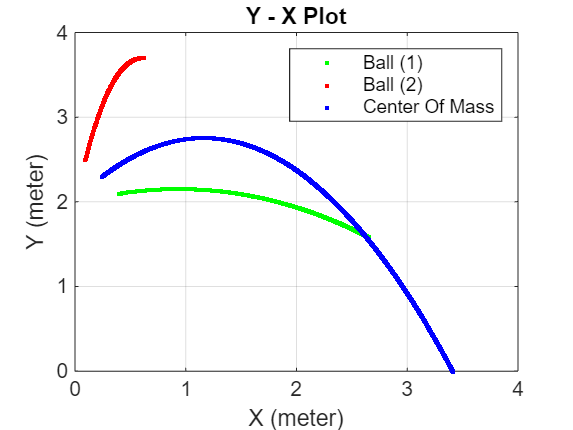

plot(X1,Y1,'.g' , X2,Y2,'.r' , Xc,Yc,'.b'); grid
xlabel('X (meter)'); ylabel('Y (meter)');
legend('Ball (1)','Ball (2)','Center Of Mass'); title('Y - X Plot');